% Ejercicio 1.
% Crea los conjuntos difusos A y B, definidos como (x, μ(x)):
mu_A=[0.1 0.3 0.7 1.0 0.6 0.2 0.1];
solution.ej1a_1 = mu_A;
mu_B=[0.2 0.8 1.0 0.6 0.4 0.3 0.1];
solution.ej1a_2 = mu_B;
% A U B
muA_union_B=max(mu_A,mu_B);
solution.ej1b_1 = muA_union_B;
% A ∩ B
muA_interseccion_B=min(mu_A,mu_B);
solution.ej1b_2 = muA_interseccion_B;
% C(B)
mu_BC = 1-mu_B;
solution.ej1b_3 = mu_BC;
% C(A U B)
muA_union_B_complementario=1-muA_union_B;
solution.ej1b_4 = muA_union_B_complementario;
% C(C(A) ∩ B)
mu_AC=1-mu_A;
muAC_interseccion_B=intersect(mu_AC,mu_B);
muAC_interseccion_B_complementario=1-muAC_interseccion_B;
solution.ej1b_5 = muAC_interseccion_B_complementario;

% Ejercicio 2.
% El producto como t-norma y la suma probabilística (x+y-xy) como tconorma
mu_A=[0.1 0.3 0.7 1.0 0.6 0.2 0.1];
mu_B=[0.2 0.8 1.0 0.6 0.4 0.3 0.1];

% A U B
muA_union_B=mu_A+mu_B-(mu_A.*mu_B);
solution.ej2a_1 = muA_union_B;
% A ∩ B
muA_interseccion_B=mu_A.*mu_B;
solution.ej2a_2 = muA_interseccion_B;
% C(B)
mu_BC=1-mu_B;
solution.ej2a_3 = mu_BC;
% C(A U B)
muA_union_B_complementario=1-muA_union_B;
solution.ej2a_4 = muA_union_B_complementario;
% C(C(A) ∩ B)
mu_AC=1-mu_A;
muAC_interseccion_B=intersect(mu_AC,mu_B);
muAC_interseccion_B_complementario=1-muAC_interseccion_B;
solution.ej2a_5 = muAC_interseccion_B_complementario;

%plot(A,muA_union_B,'oc',A,muA_interseccion_B,'+r',A,mu_BC,'xk',A,muA_union_B_complementario,'sg',A,muAC_interseccion_B_complementario,'dm');
%legend('A union B', 'A interseccion B', 'B complementario', 'C(AUB)', 'C(C(A)∩B)');

% Lukasievitz como t-norma (max(0, x+y-1)) y su t-conorma dual (min(1,x+y)).
A=1:7;
mu_A=[0.1 0.3 0.7 1.0 0.6 0.2 0.1];
mu_B=[0.2 0.8 1.0 0.6 0.4 0.3 0.1];
% A U B
muA_union_B=union(1,mu_A+mu_B);
solution.ej2b_1 = muA_union_B;
% A ∩ B
muA_interseccion_B=intersect(0,mu_A+mu_B-1);
solution.ej2b_2 = muA_interseccion_B;
% C(B)
mu_BC=1-mu_B;
solution.ej2b_3 = mu_BC;
% C(A U B)
muA_union_B_complementario=1-muA_union_B;
solution.ej2b_4 = muA_union_B_complementario;
% C(C(A) ∩ B)
mu_AC=1-mu_A;
muAC_interseccion_B=intersect(mu_AC,mu_B);
muAC_interseccion_B_complementario=1-muAC_interseccion_B;
solution.ej2b_5 = muAC_interseccion_B_complementario;

%plot(A,muA_union_B,'oc',A,muA_interseccion_B,'+r',A,mu_BC,'xk',A,muA_union_B_complementario,'sg',A,muAC_interseccion_B_complementario,'dm');
%legend('A union B', 'A interseccion B', 'B complementario', 'C(AUB)', 'C(C(A)∩B)');

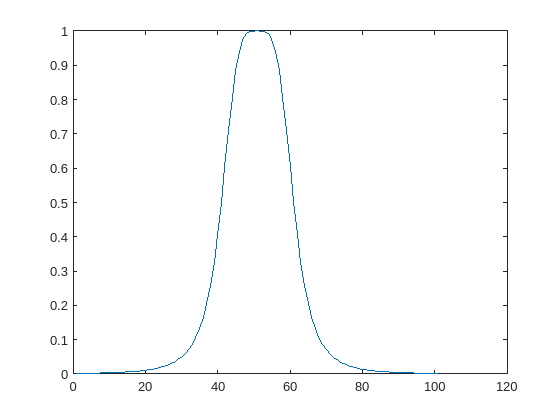

% Ejercicio 3.
% En este ejercicio vamos a definir conjuntos difusos para ofrecer
% sensación de continuidad sobre el referencial. Para ello, vamos a utilizar un
% referencial X que comience en 0 y acabe en 10 y vamos a considerar todos los
% elementos de dicho intervalo con saltos de 0.1 en 0.1. Utilizando dicho
% referencial crear los siguientes conjuntos difusos:

x=0:0.1:10;
mu_f=1./(1+(x-5).^4);
plot(mu_f)

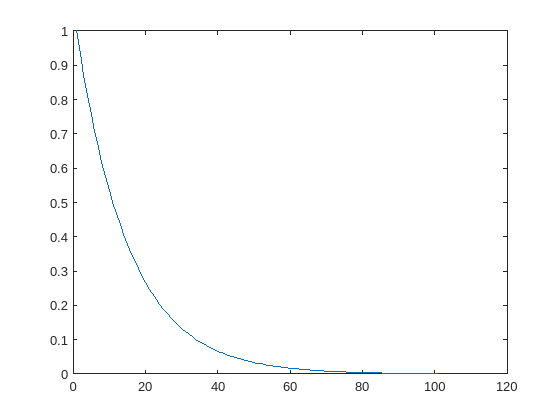

mu_g=2.^-x;
plot(mu_g)

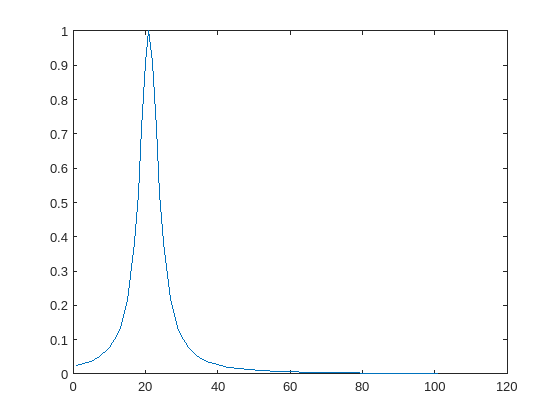

mu_h=1./(1+10*(x-2).^2);
plot(mu_h)

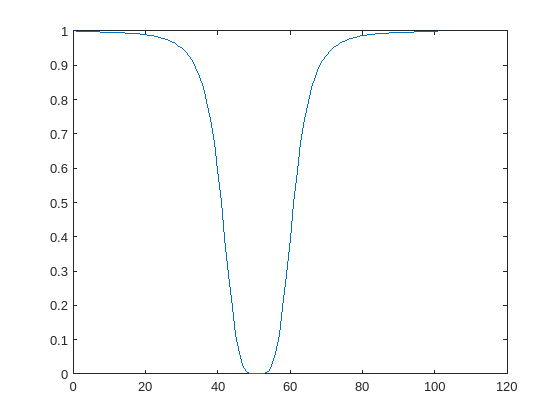

% C(F), C(H) y C(G)
complementario_f=1-mu_f;
plot(complementario_f)

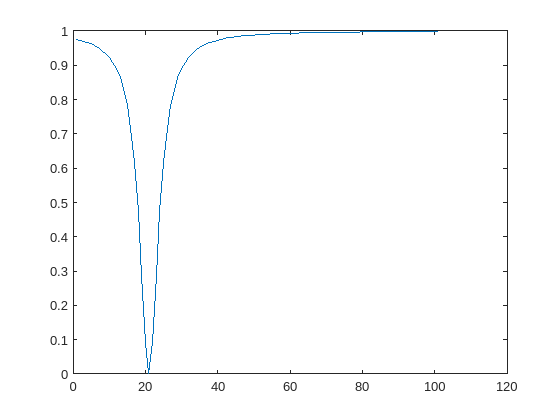

complementario_h=1-mu_h;
plot(complementario_h)

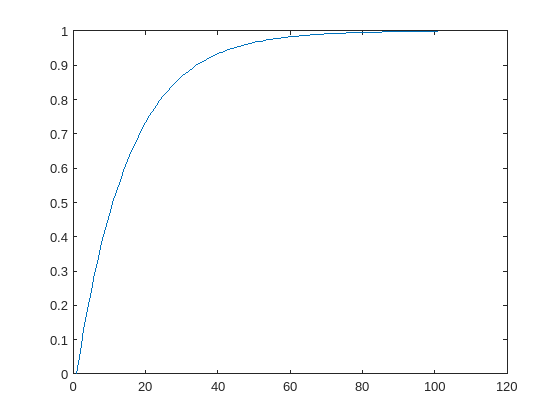

complementario_g=1-mu_g;
plot(complementario_g)

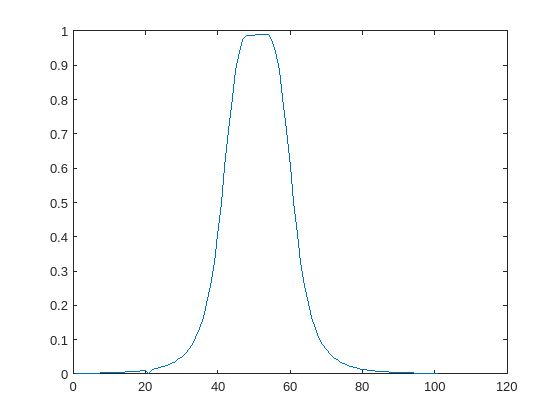

% F∩C(H), C(C(G) ∩ H), C(F U H)
uno=min(mu_f,complementario_h);
plot(uno)

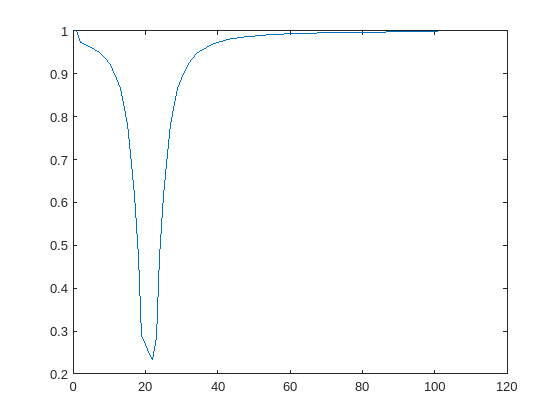

dos=1-min(complementario_g,mu_h);
plot(dos)

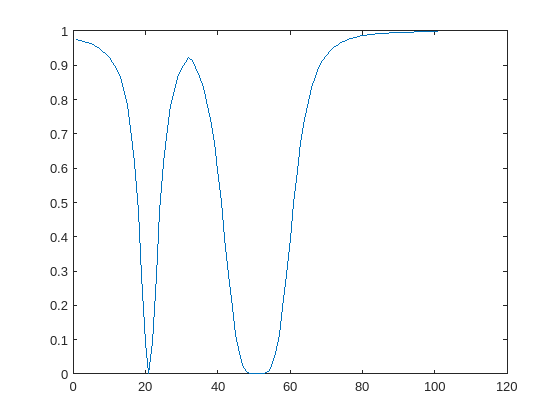

tres=1-max(mu_f,mu_h);
plot(tres)

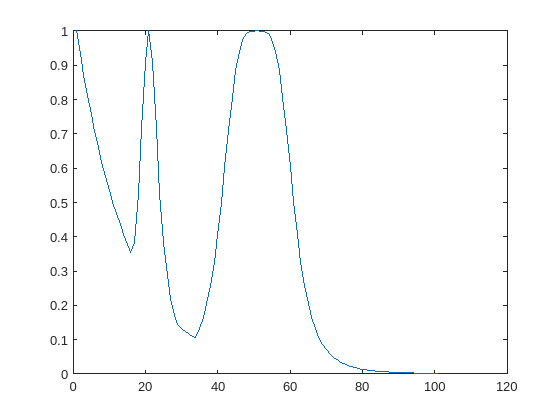

% F U G U H, F ∩ G ∩ H
f_union_g_union_h=max(max(mu_f,mu_g),mu_h);
plot(f_union_g_union_h)

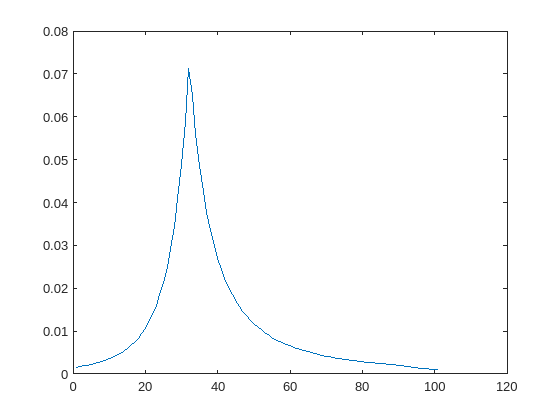

f_interseccion_g_intersecion_h=min(min(mu_f,mu_g),mu_h);
plot(f_interseccion_g_intersecion_h)

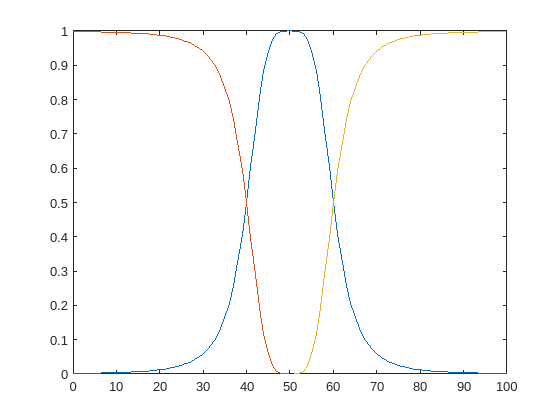

% Ejercicio 4

adulto=0:100;
mu_adulto=1./(1.+((adulto-50)/10).^4);
plot(adulto, mu_adulto)
hold on;
[adulto,medio]=max(mu_adulto);
x=0:medio-1;
y=medio:100;
mu_joven=1-(1./(1.+((x-50)/10).^4));
plot(x, mu_joven)
mu_anciano=1-(1./(1.+((y-50)/10).^4));
plot(y, mu_anciano)
hold off;

Ejercicio 5

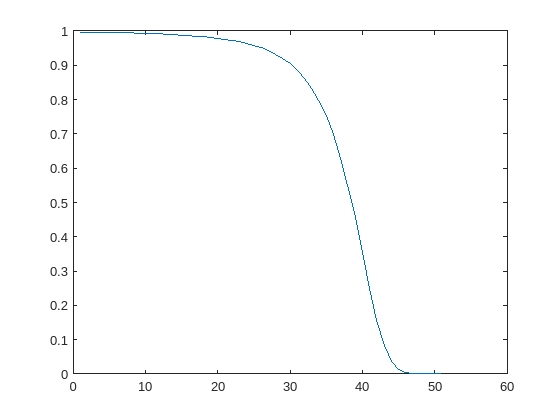

muy_joven=mu_joven.^2;
plot(muy_joven)

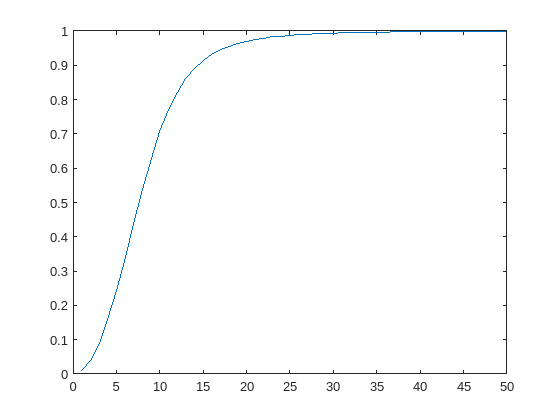

bastante_anciano=mu_anciano.^(0.5);
plot(bastante_anciano)

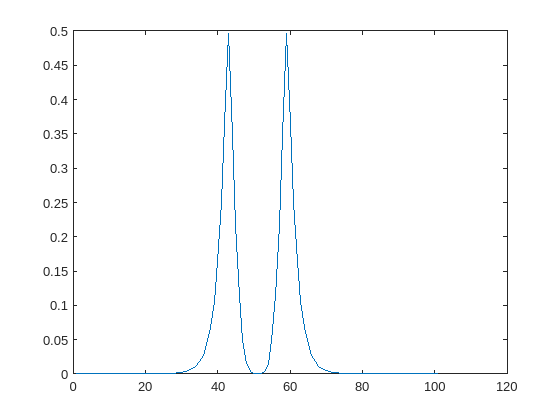

ligeramente_adulto=min((mu_adulto.^2),1-(mu_adulto.^2));
plot(ligeramente_adulto)